# V768 - Measuring Vision with Psychophysics

## Lab 4 - Contrast Sensitivity Functions

In Lab 3, you learned that a **psychometric function** models the relationship between a given stimulus feature (e.g., contrast) and a participant's forced-choice responses and that psychometric functions are ***inferential models***, meaning that they allow you to infer certain things about the relationship that they model. But what you can infer once you've fit a psychometric function to data? And how does this work across multiple experimental conditions?

In this lab, you'll learn about inferring ***threshold*** and ***sensitivity*** from psychometric functions and about how those numbers allow you to analyze performance when two stimulus features vary. You'll use that knowledge to plot your **contrast sensitivity function** (aka modulation transfer function).

### Learning Outcomes

(i.e., what you will be able to do at the end of this lab)

- Describe how threshold and sensitivity are measured from a psychometric curve.

- Explain how forced-choice responses can be analyzed when an experiment involves varying more than one stimulus feature.

- Describe what a contrast sensitivity function is and how to measure one.

### Questions

- Include and write a caption for the figure in Part A, Step 3 (altering contrast sensitivity).

- For the Part A, Step 3 figure, explain the differences between the three curves. What caused them to be different from one another? What impact did that have on the contrast perception represented by each curve?

- Include and write a caption for the figure in Part C, Step 4 (data and fitted curves).

- Include and write a caption for the figure in Part C, Step 5 (threshold and sensitivity).

- What do threshold and sensitivity values tell you about an observer's sensation/perception?

- If you were presenting results from your own forced choice experiment (in a poster, talk, paper, etc.), do you think you would prefer presenting thresholds or sensitivities? Explain why, discussing pros and cons of both options.

## Part A. Simulate Psychometric Functions

Psychometric functions are a fundamental part of psychophysics research. Lab 3 introduced you to psychometric functions and gave you some experience with fitting a psychometric function to contrast sensitivity data from **simple forced choice** (yes-no) and **two-alternative forced choice (2AFC)** experiments. With that experience under your belt, let's go over a few key points and use a simulation to build your understanding.

#### **Why all this talk about psychometric functions?**

A **function** is a mathematical rule that governs how one number is related to another. For $y=f\left(x\right)$, function $f$ defines how you can mathematically transform $x$ into $y$. One example is the slope-intercept equation of a line: $y=f\left(x;m,b\right)=\textrm{mx}+b$. In this case, function $f$ with parameters $m$ and $b$ describes the linear relationship between $x$ and $y$.

**Psychophysics** aims to measure the relationship between a physical stimulus and an observer's resulting sensory/perceptual experiences, so a key tool in psychophysics is the **psychometric function**: a mathematical rule that governs how stimuli are related to an observer's responses. For $p=\psi \left(x\right)$, function $\psi$ defines how you can mathematically transform $x$, a quantified feature of the stimulus (e.g., contrast, spatial frequency), into $p$, a probability of a certain behavioral response (e.g., probability detected, probability correct).

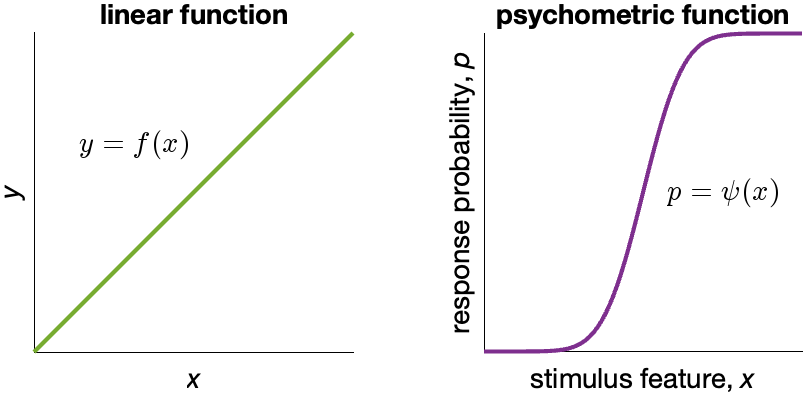

#### **How do you use a psychometric function?**

In an experiment, you repeatedly show an observer stimuli for each of your stimulus conditions (e.g., each of your chosen contrast levels). You record the observer's behavioral responses, and per condition, you calculate the probability of each possible response (e.g., at 0.4% contrast, probability detected = 0.75 & probability not detected = 0.25). You then fit a psychometric function to your data.

The fitted function most likely won't match the data exactly because of the variability of the observer's perception and their motor responses (e.g., they may click "yes" when they meant to click "no"), but a well-fit function will allow you to accurately summarize the entire curve with one number: a number you ***infer*** from the ***inferential model ***you've fit to your data. Psychometric functions thereby allow you to make your experiment more complex (e.g., by varying more than one stimulus feature) without making your data notably more difficult to interpret.

### Step 1. Create an example psychometric function

In Lab 3, we used the psychometric equation 


$$\mathbf{p}=\psi \left(\mathbf{x};\mu ,\sigma ,\gamma ,\lambda \right)=\textrm{CDF}\left(\mathbf{x};\mu ,\sigma \right)\cdot \left(1-\gamma -\lambda \right)+\gamma$$


where $\psi$ is the psychometric function, $\mathbf{x}$ is the set of stimulus levels (the input of function $\psi$), $\mathbf{p}$ is the set of response probabilities (the output of function $\psi$), $\mu$ is the mean of the underlying cumulative density function (CDF), $\sigma$ is the standard deviation of that CDF, $\gamma$ is the guess rate, and $\lambda$ is the lapse rate.

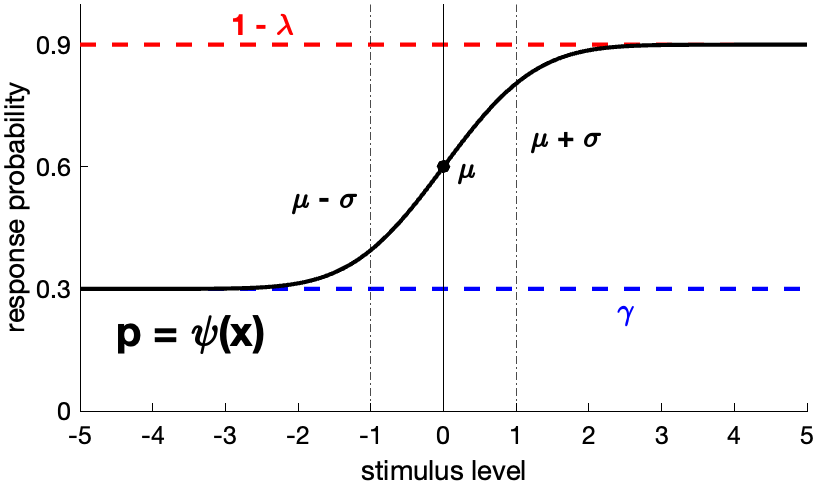

#### Define a function for a 2AFC task

Think back to the 2AFC task from Lab 3. Sinusoidal gratings of different contrast levels were shown on either the left or right side of the screen, and you had to choose between left and right, even if you didn't see a stimulus. Because you had two alternatives, you had a 50% chance of being correct just by guessing.

Let's make an example curve for that task and see what it looks like.

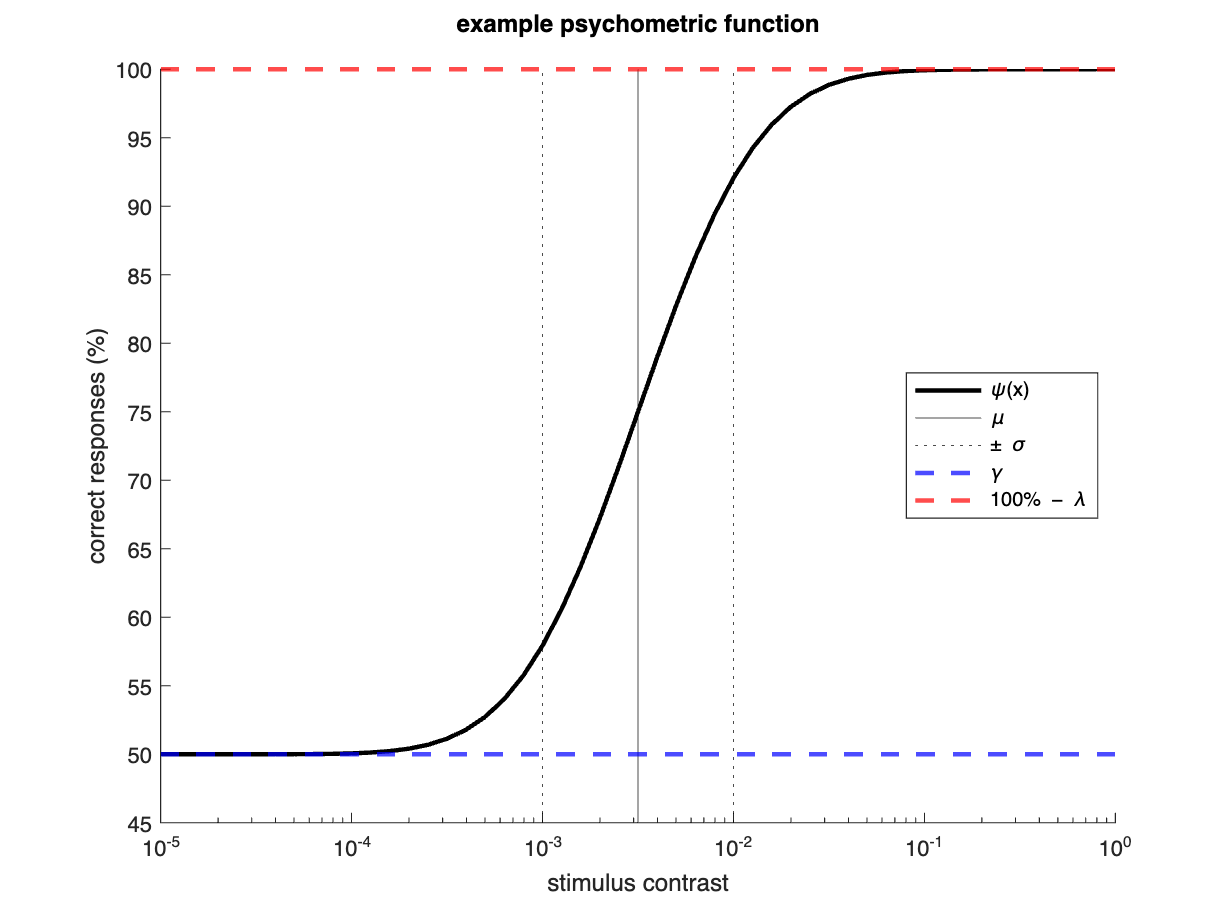

% define psychometric function
psyfxn = @(c,x) (normcdf(x, c(1), c(2)) * (1 - c(3) - c(4))) + c(3);
% c(1) = mu
% c(2) = sigma
% c(3) = guess rate
% c(4) = lapse rate

% define example parameters
psy_ex.mu = -2.5; psy_ex.sig = .5;
psy_ex.r_guess = .5; psy_ex.r_lapse = 0;
psy_ex.params = [psy_ex.mu, psy_ex.sig, psy_ex.r_guess, psy_ex.r_lapse];

% create example curve
psy_ex.curve_x = 10.^(-5:.1:0);
psy_ex.curve_y = psyfxn(psy_ex.params, log10(psy_ex.curve_x));

% stash RGB values for default MATLAB colors
% (blue, orange, gold, purple, green, sky blue, red)
rgb_matlab = [0, 0.447, 0.741; 0.85, 0.325, 0.098; 0.929, 0.694, 0.125; ...
    0.494, 0.184, 0.556; 0.466, 0.674, 0.188; 0.301, 0.745, 0.933; 0.635, 0.078, 0.184];

% plot example curve
figure; hold on;
plot(psy_ex.curve_x, psy_ex.curve_y*100, 'k', 'LineWidth',2)
set(gca,'XScale','log')
y_min = 45; ylim([y_min,100])
title(["example psychometric function",""])
xlabel("stimulus contrast")
ylabel("correct responses (%)")

% mark parameter values
xline(10.^psy_ex.mu, 'k-')
xline(10.^(psy_ex.mu+psy_ex.sig), 'k:')
xline(10.^(psy_ex.mu-psy_ex.sig), 'k:')
yline(psy_ex.r_guess * 100, 'b--', 'LineWidth',2)
yline((1-psy_ex.r_lapse) * 100, 'r--', 'LineWidth',2)
legend(["\psi(x)", "\mu", "\pm \sigma", "", ...
    "\gamma", "100% "+char(0x2212)+" \lambda"], ...
    'Location','east')

drawnow

This plot shows our example psychometric curve and illustrates our curve's parameters. Recall that $\mu$ and $\sigma$ control the curve's central tendency and spread (x-axis), while $\gamma$ and $\lambda$ control the curve's floor and ceiling (y-axis).

### Step 2. Create a function for a more sensitive observer

Changing $\mu$ will change the location of the curve's center along the x-axis. An observer with a lower $\mu$ would be better at detecting (i.e., more sensitive to) low contrast stimuli than the observer that the curve above represents. Hence, their overall performance on the task would be better, so let's create a curve representing a more sensitive observer by lowering $\mu$.

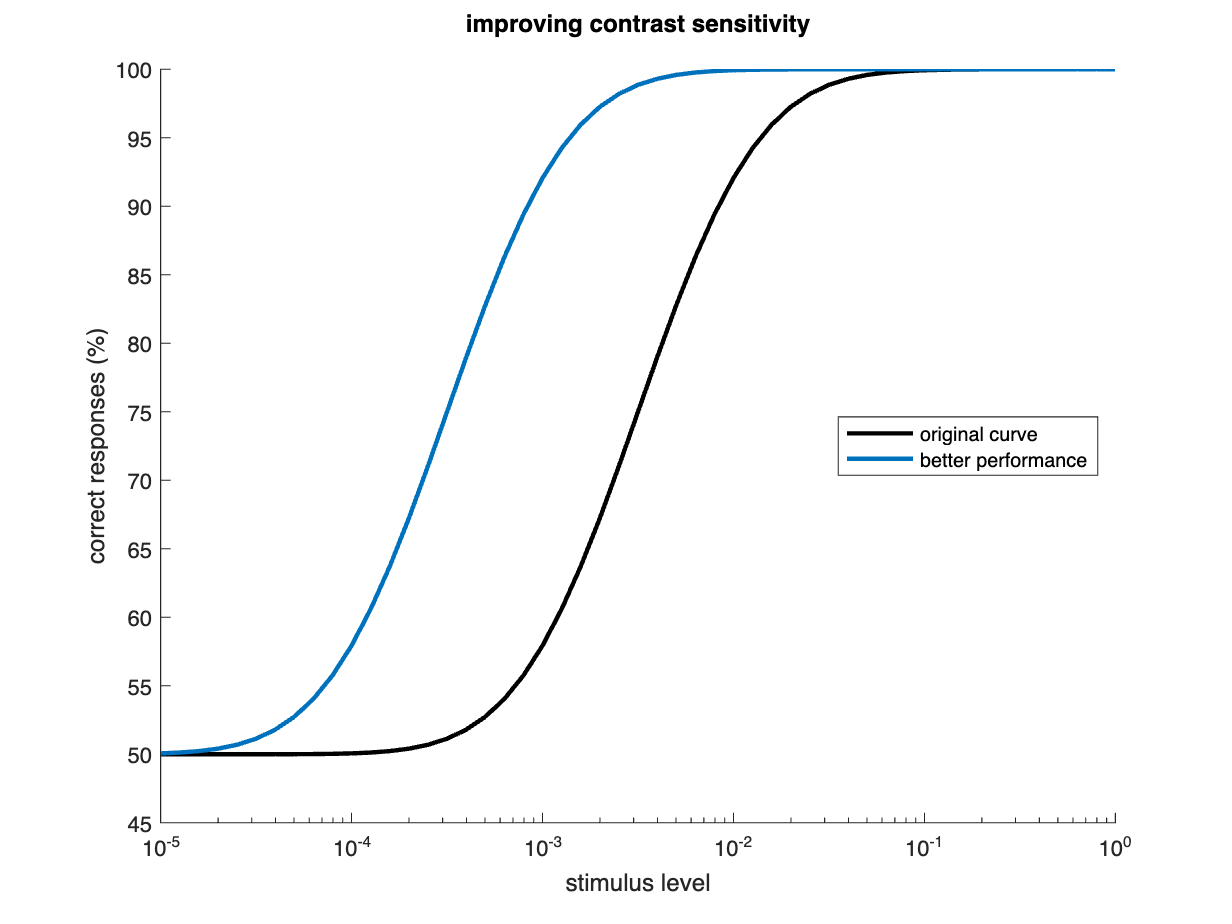

% build a curve with a lower mu
psy_better.mu = psy_ex.mu - 1;
psy_better.params = [psy_better.mu, psy_ex.sig, psy_ex.r_guess, psy_ex.r_lapse];
psy_better.curve_y = psyfxn(psy_better.params, log10(psy_ex.curve_x));

% plot the original example psychometric function
figure; hold on;
plot(psy_ex.curve_x, psy_ex.curve_y*100, 'k', 'LineWidth',2)
set(gca,'XScale','log')
ylim([45,100])
xlabel("stimulus level")
ylabel("correct responses (%)")

% plot the better curve
plot(psy_ex.curve_x, psy_better.curve_y*100, 'LineWidth',2, 'Color',rgb_matlab(1,:))
title(["improving contrast sensitivity",""])
legend(["original curve","better performance"], 'Location','east')

drawnow

### Step 3. Create a function for a less sensitive observer

Let's stick with changing our $\mu$ value. An observer with a lower $\mu$ would be worse at detecting (i.e., less sensitive to) low contrast stimuli than the observers that our existing curves represent, meaning their overall performance on the task would be worse. Here, let's create a curve representing a less sensitive observer by increasing $\mu$ by half as much as we decreased it.

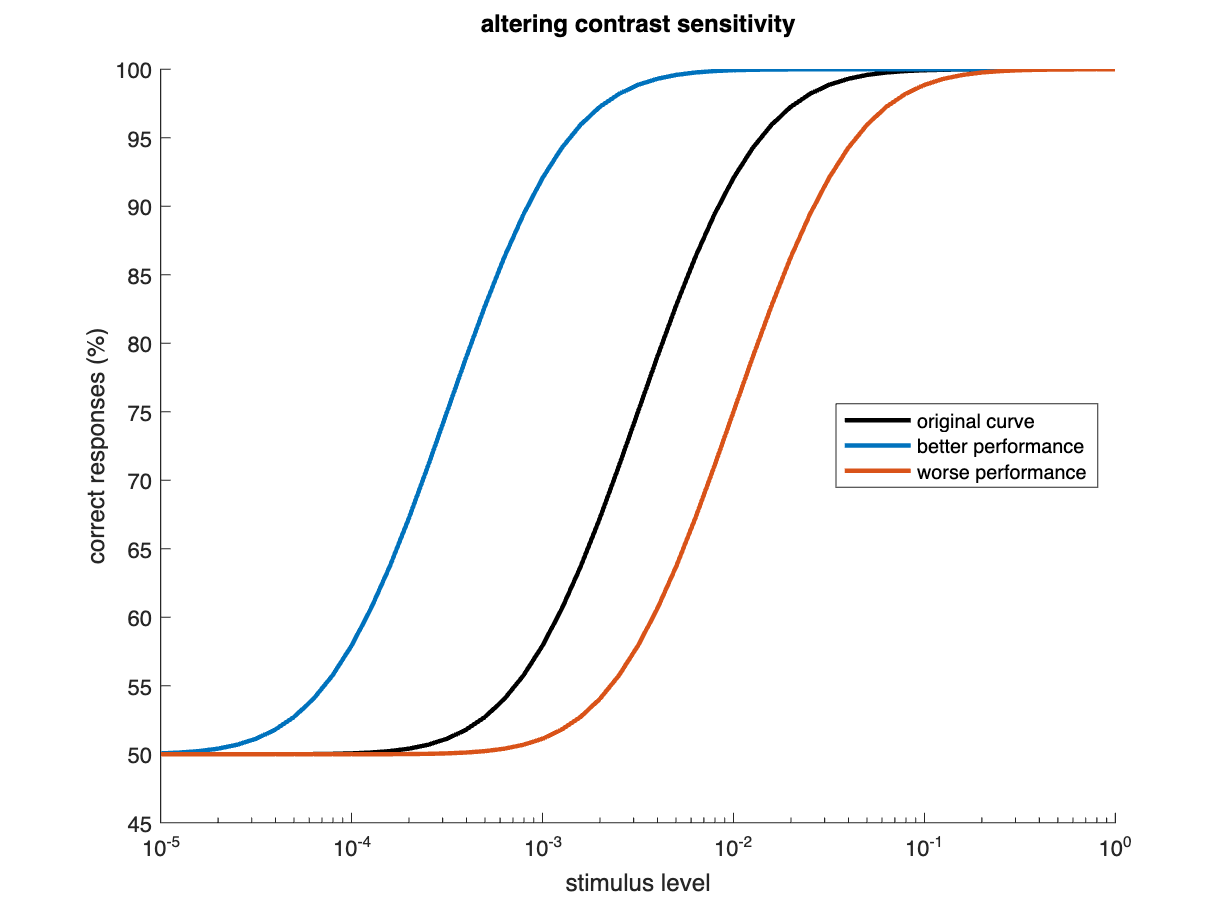

% build a curve with a higher mu and sigma
psy_worse.mu = psy_ex.mu + (abs(psy_ex.mu - psy_better.mu)/2);
psy_worse.params = [psy_worse.mu, psy_ex.sig, psy_ex.r_guess, psy_ex.r_lapse];
psy_worse.curve_y = psyfxn(psy_worse.params, log10(psy_ex.curve_x));

% plot the existing example psychometric functions
figure; hold on;
plot(psy_ex.curve_x, psy_ex.curve_y*100, 'k', 'LineWidth',2)
plot(psy_ex.curve_x, psy_better.curve_y*100, 'LineWidth',2, 'Color',rgb_matlab(1,:))
set(gca,'XScale','log')
ylim([45,100])
xlabel("stimulus level")
ylabel("correct responses (%)")

% plot the worse curve
plot(psy_ex.curve_x, psy_worse.curve_y*100, 'LineWidth',2, 'Color',rgb_matlab(2,:))
title(["altering contrast sensitivity",""])
legend(["original curve", "better performance", "worse performance"], ...
    'Location','east')

drawnow

Now we have three curves, each of which represents the performance of a theoretical perceptual system on a 2AFC contrast sensitivity task. We have our original example, a curve for an observer who is better at our task, and a curve for an observer who is worse at our task.

### Step 4. Confirm that overall performance would change

As you learned when simulating a signal detection experiment in Lab 2, it's always good to double check the results of your programming when building a simulation, so let's double check that the changes we made would impact overall performance on an experiment.

We wouldn't run an experiment with all of the contrast levels included in our curves, so let's first pick a more reasonable number of contrast values.

sim_expt = table;
sim_expt.log_levels = (log10(psy_ex.curve_x(1)):log10(psy_ex.curve_x(end))).';
sim_expt.levels = 10.^sim_expt.log_levels;
fprintf("number of levels = %i", length(sim_expt.levels))

number of levels = 6

Next, we need to find the response probabilities for those contrast levels.

sim_expt.ex = psyfxn(psy_ex.params, sim_expt.log_levels);
sim_expt.better = psyfxn(psy_better.params, sim_expt.log_levels);
sim_expt.worse = psyfxn(psy_worse.params, sim_expt.log_levels);
disp(sim_expt)

    log_levels    levels      ex       better      worse 
    __________    ______    _______    _______    _______

        -5         1e-05        0.5    0.50067        0.5
        -4        0.0001    0.50067    0.57933    0.50002
        -3         0.001    0.57933    0.92067    0.51138
        -2          0.01    0.92067    0.99933       0.75
        -1           0.1    0.99933          1    0.98862
         0             1          1          1    0.99998



Finally, we can calculate the overall performance associated with each curve on this "experiment" by averaging across the probabilities per contrast level.

sim_prob = varfun(@mean, sim_expt);
sim_prob = array2table([sim_prob.mean_ex, sim_prob.mean_better, ...
    sim_prob.mean_worse], 'VariableNames',["ex", "better", "worse"]);
disp(sim_prob)

     ex     better      worse 
    ____    _______    _______

    0.75    0.83333    0.70833



So, **did our changes have the impact we intended? **Is the "better" probability higher than the original example ("ex")? Is the "worse" probability lower than the example?

## Part B. Making Inferences from Psychometric Functions

Recall our psychometric equation: 


$$\mathbf{p}=\psi \left(\mathbf{x};\mu ,\sigma ,\gamma ,\lambda \right)=\textrm{CDF}\left(\mathbf{x};\mu ,\sigma \right)\cdot \left(1-\gamma -\lambda \right)+\gamma$$


When we put stimulus levels $\mathbf{x}$ into function $\psi$, we get back a set of response probabilties $\mathbf{p}$.

What if instead we want to input a response probability and find out the corresponding stimulus level? To do that, we need to ***invert*** our equation. In other words, we need to swap things around to go from our function $\mathbf{p}=\psi \left(\mathbf{x}\right)$ to its **inverse**, function $\mathbf{x}=\psi^{-1} \left(\mathbf{p}\right)$.

To isolate $\mathbf{x}$ on one side of the equation, we can first use algebra to isolate $\textrm{CDF}\left(\mathbf{x}\right)$:


$$\mathbf{p}=\textrm{CDF}\left(\mathbf{x}\right)\cdot \left(1-\gamma -\lambda \right)+\gamma$$



$$\mathbf{p}-\gamma =\textrm{CDF}\left(\mathbf{x}\right)\cdot \left(1-\gamma -\lambda \right)$$



$$\frac{\mathbf{p}-\gamma }{1-\gamma -\lambda }=\textrm{CDF}\left(\mathbf{x}\right)$$


We can then fully isolate $\mathbf{x}$ using the inverse of the cumulative density function (${\textrm{CDF}}^{-1}$):


$${\textrm{CDF}}^{-1} \left(\textrm{CDF}\left(\mathbf{x}\right)\right)={\textrm{CDF}}^{-1} \left(\frac{\mathbf{p}-\gamma }{1-\gamma -\lambda }\right)$$



$$\mathbf{x}={\textrm{CDF}}^{-1} \left(\frac{\mathbf{p}-\gamma }{1-\gamma -\lambda }\right)$$


With the parameters of each function included (noted after a semicolon), this gives us the inverse psychometric equation


$$\mathbf{x}=\psi^{-1} \left(\mathbf{p};\mu ,\sigma ,\gamma ,\lambda \right)={\textrm{CDF}}^{-1} \left(\frac{\mathbf{p}-\gamma }{1-\gamma -\lambda };\mu ,\sigma \right)$$


Now we have the ability to put a set of response probabilties $\mathbf{p}$ into inverse function $\psi^{-1}$ and get back stimulus levels $\mathbf{x}$.

### Step 1. Use the inverse psychometric function

Let's give that a try with the original example psychometric function we created above. We'll pick several different response probabilities, put them into the inverse of our example function, and see what stimulus levels we get back.

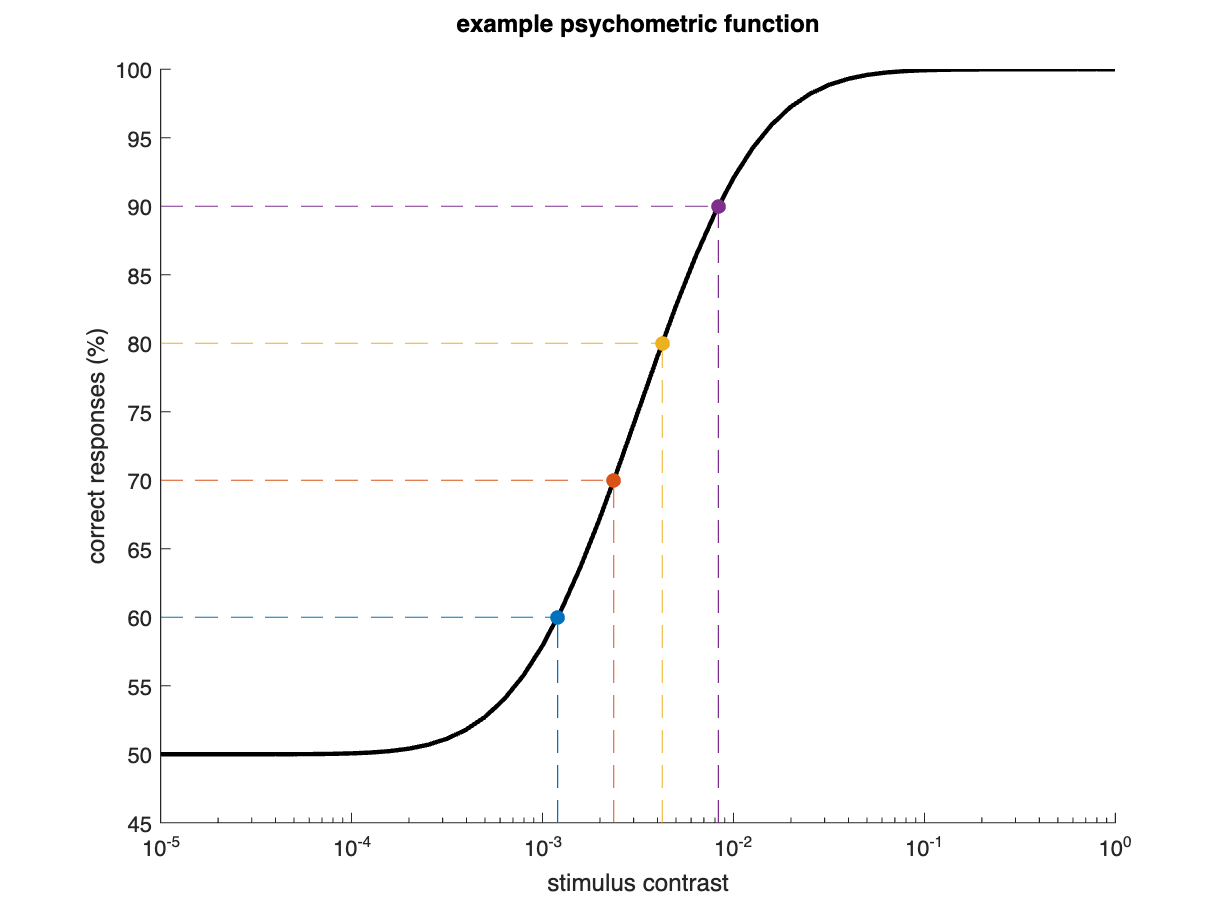

% define inverse psychometric function
ipsyfxn = @(c,p) norminv((p - c(3))/(1 - c(3) - c(4)), c(1), c(2));
% c(1) = mu
% c(2) = sigma
% c(3) = guess rate
% c(4) = lapse rate

% use response values to find stimulus values
psy_ex.y_vals = (.6:.1:.9).';
psy_ex.log_x_vals = ipsyfxn(psy_ex.params, psy_ex.y_vals);
psy_ex.x_vals = 10.^psy_ex.log_x_vals;

% plot example curve
figure; hold on;
plot(psy_ex.curve_x, psy_ex.curve_y*100, 'k', 'LineWidth',2)
set(gca,'XScale','log')
ylim([y_min,100])
title(["example psychometric function",""])
xlabel("stimulus contrast")
ylabel("correct responses (%)")

% mark calculated values
for i_val=1:length(psy_ex.y_vals)
    this_x = psy_ex.x_vals(i_val); this_y = psy_ex.y_vals(i_val)*100;
    plot([psy_ex.curve_x(1), this_x], [this_y, this_y], ...
        '--', 'Color',rgb_matlab(i_val,:))
    plot([this_x, this_x], [y_min, this_y], ...
        '--', 'Color',rgb_matlab(i_val,:))
    plot(this_x, this_y, ...
        '.', 'Color',rgb_matlab(i_val,:), 'MarkerSize',20);
end

drawnow
disp(table(psy_ex.y_vals, psy_ex.log_x_vals, 'VariableNames',["p","log(x)"]))

     p     log(x) 
    ___    _______

    0.6    -2.9208
    0.7    -2.6267
    0.8    -2.3733
    0.9    -2.0792



**What do you think?** Does it look like our inverse function returned the right stimulus levels?

### Step 2. Measure threshold

Experimenters are often interested in measuring more than one psychometric function, so they try to find ways of summarizing each function with a single number. One common strategy for summarizing psychometric functions is finding the **threshold**.

**What is a threshold?** In psychophysics, a threshold is the stimulus level that forms a ***boundary*** between when the participant can and cannot do the task. That boundary may be clear in some circumstances, but perceptual performance tends to vary ***continuously*** across an experiment's stimulus levels (hence, the typical S-shape of psychometric curves). In other words, there may be a boundary ***line***, but usually, there's more of a boundary ***zone***. Because boundary ***zones*** are more common, the point of finding thresholds is less about the exact numbers you find and more about how the numbers you find ***compare*** to one another.

**How do you calculate threshold? **Typically, an experimenter finds a threshold value by choosing a specific response probability and calculating the stimulus level associated with that response probabiliy. Choosing a response probability is usually a somewhat arbitrary decision, but a common choice is 0.75 (75%).

#### Find the threshold of an example curve

Let's start by finding the threshold value of our original example psychometric function.

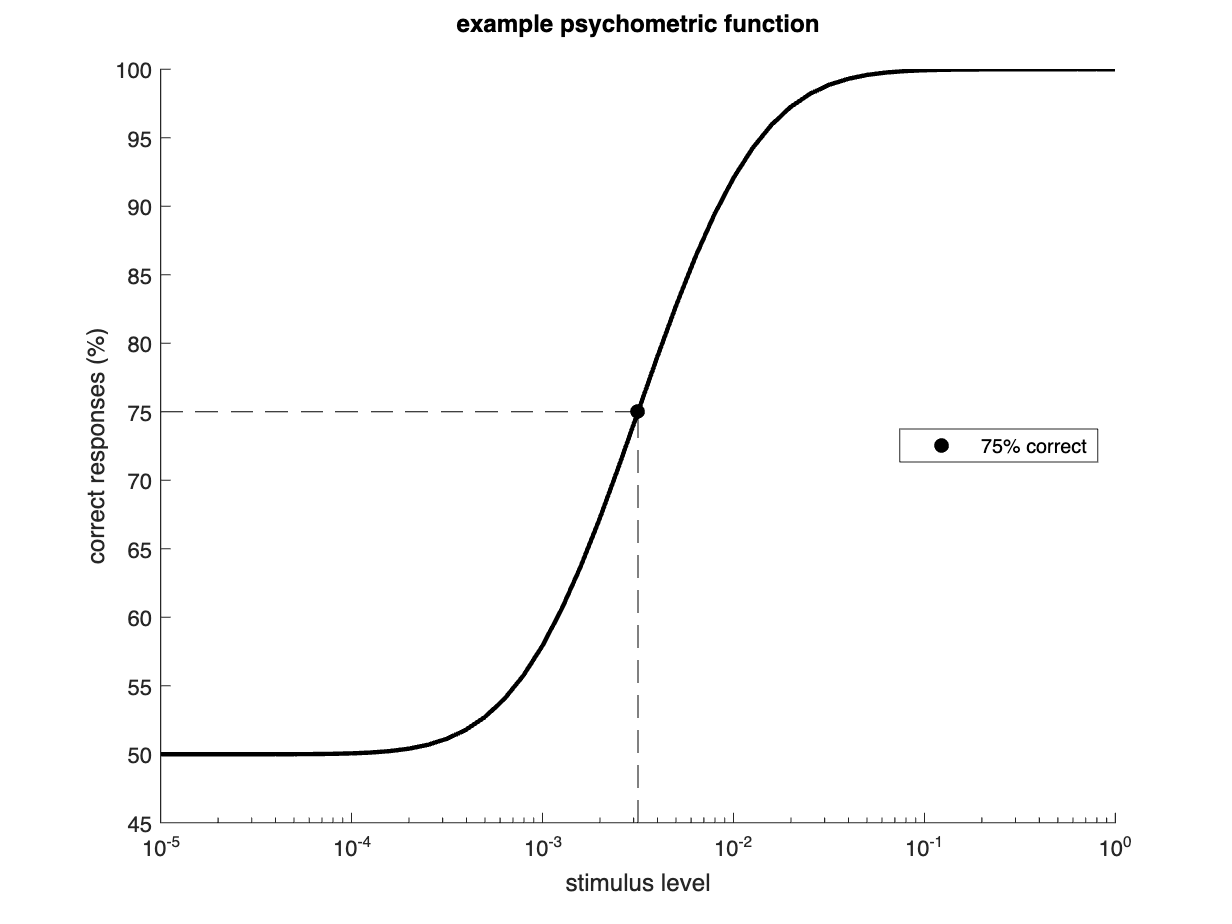

% compute the 75% mark for this psychometric curve
thresh_perc = 75; thresh_prob = thresh_perc/100;
psy_ex.threshold = 10.^(ipsyfxn(psy_ex.params, thresh_prob));

% plot the example psychometric function
figure; hold on;
plot(psy_ex.curve_x, psy_ex.curve_y*100, 'k', 'LineWidth',2)
set(gca,'XScale','log')
ylim([45,100])
title(["example psychometric function",""])
xlabel("stimulus level")
ylabel("correct responses (%)")

% add the 75% mark
plot([psy_ex.curve_x(1), psy_ex.threshold], [thresh_perc, thresh_perc], 'k--')
plot([psy_ex.threshold, psy_ex.threshold], [45, thresh_perc], 'k--')
dot_handle = plot(psy_ex.threshold, thresh_perc, 'k.', 'MarkerSize',20);
legend(dot_handle, {[num2str(thresh_perc) '% correct']}, ...
    'Location','east')

drawnow

For our example curve, the 75% threshold is

fprintf("10^%g \n",log10(psy_ex.threshold))

10^-2.5 


#### Find the threshold of a "better" curve

What about our curve with improved task performance? An observer with a lower $\mu$ would be **better** at detecting low contrast stimuli, so will lowering $\mu$ **increase** or **decrease** the threshold value?

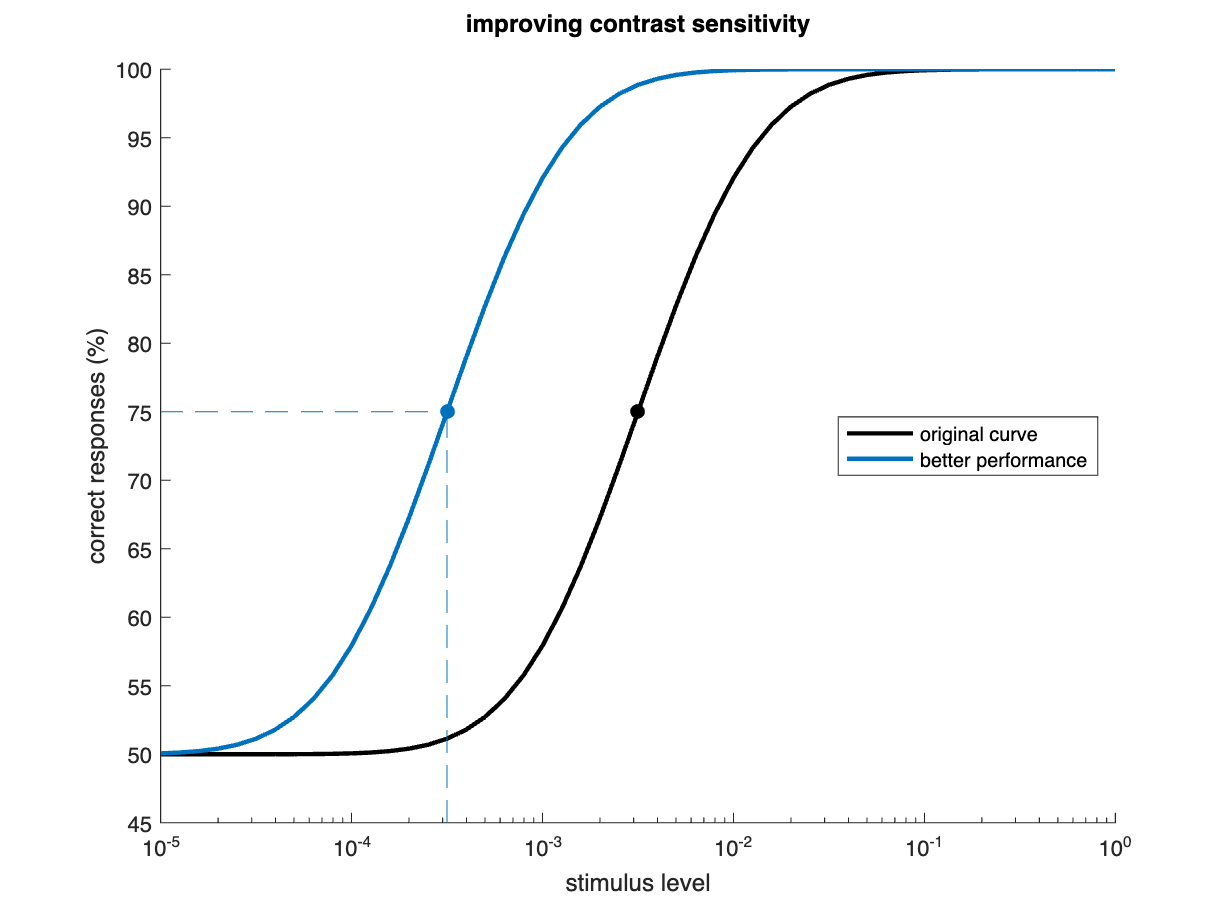

% compute the 75% mark for better psychometric curve
psy_better.threshold = 10.^(ipsyfxn(psy_better.params, thresh_prob));

% plot the original example psychometric function
figure; hold on;
plot(psy_ex.curve_x, psy_ex.curve_y*100, 'k', 'LineWidth',2)
plot(psy_ex.threshold, thresh_perc, 'k.', 'MarkerSize',20)
set(gca,'XScale','log')
ylim([45,100])
xlabel("stimulus level")
ylabel("correct responses (%)")

% plot the better curve
plot(psy_ex.curve_x, psy_better.curve_y*100, ...
    'LineWidth',2, 'Color',rgb_matlab(1,:))
plot([psy_ex.curve_x(1), psy_better.threshold], [thresh_perc, thresh_perc], ...
    '--', 'Color',rgb_matlab(1,:))
plot([psy_better.threshold, psy_better.threshold], [45, thresh_perc], ...
    '--', 'Color',rgb_matlab(1,:))
plot(psy_better.threshold, thresh_perc, ...
    '.', 'MarkerSize',20, 'Color',rgb_matlab(1,:))
title(["improving contrast sensitivity",""])
legend(["original curve","","better performance"], ...
    'Location','east')

drawnow

For our "better" curve, the 75% threshold is

fprintf("10^%g \n",log10(psy_better.threshold))

10^-3.5 


#### Find the threshold of a "worse" curve

Finally, what about our curve with the worst task performance? An observer with a higher $\mu$ would be **worse** at detecting low contrast stimuli, so will raising $\mu$ **increase** or **decrease** the threshold value?

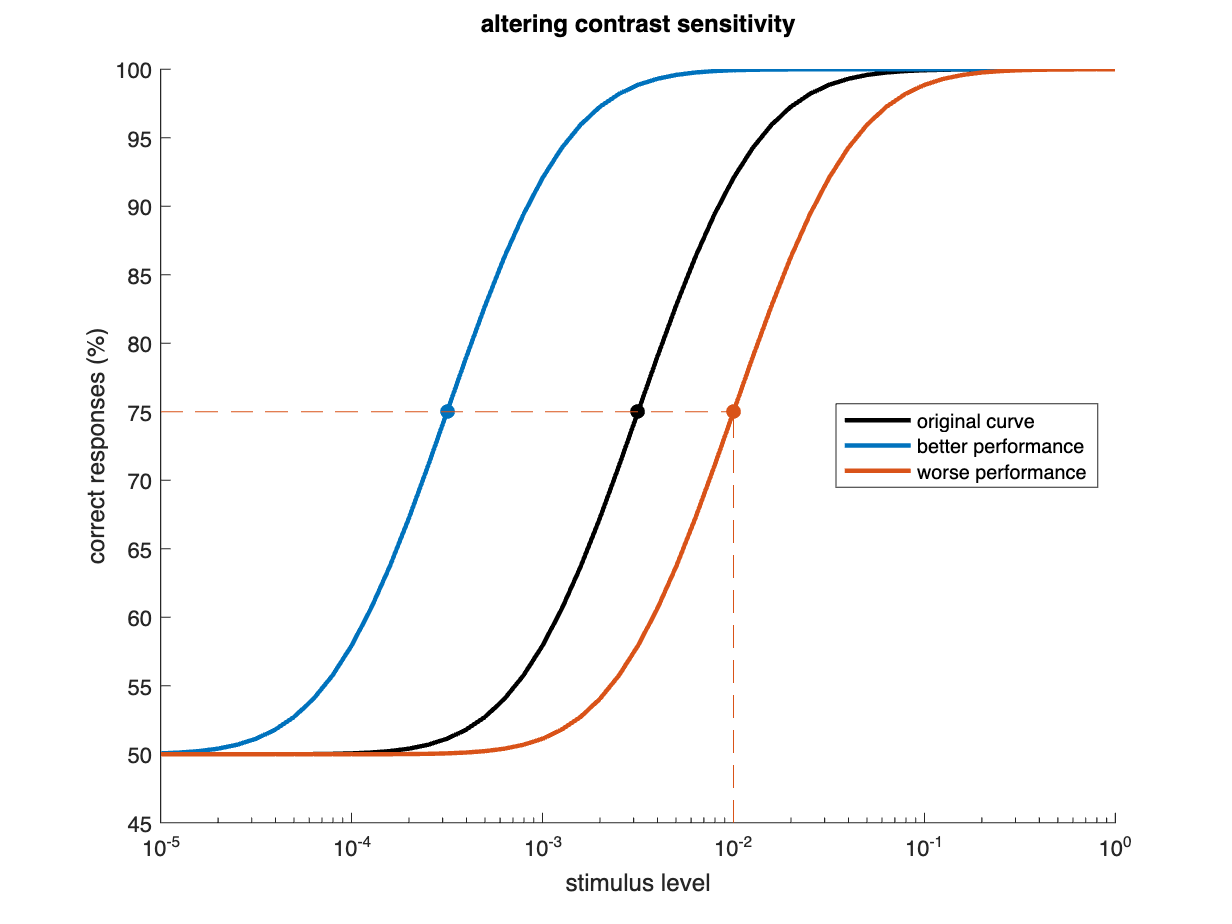

% compute the 75% mark for worse psychometric curve
psy_worse.threshold = 10.^(ipsyfxn(psy_worse.params, thresh_prob));

% plot the original example psychometric function
figure; hold on;
plot(psy_ex.curve_x, psy_ex.curve_y*100, 'k', 'LineWidth',2)
plot(psy_ex.threshold, thresh_perc, 'k.', 'MarkerSize',20)
set(gca,'XScale','log')
ylim([45,100])
xlabel("stimulus level")
ylabel("correct responses (%)")

% add the better curve
plot(psy_ex.curve_x, psy_better.curve_y*100, ...
    'LineWidth',2, 'Color',rgb_matlab(1,:))
plot(psy_better.threshold, thresh_perc, ...
    '.', 'MarkerSize',20, 'Color',rgb_matlab(1,:))

% add the worse curve
plot(psy_ex.curve_x, psy_worse.curve_y*100, ...
    'LineWidth',2, 'Color',rgb_matlab(2,:))
plot([psy_ex.curve_x(1), psy_worse.threshold], [thresh_perc, thresh_perc], ...
    '--', 'Color',rgb_matlab(2,:))
plot([psy_worse.threshold, psy_worse.threshold], [45, thresh_perc], ...
    '--', 'Color',rgb_matlab(2,:))
plot(psy_worse.threshold, thresh_perc, ...
    '.', 'MarkerSize',20, 'Color',rgb_matlab(2,:))
title(["altering contrast sensitivity",""])
legend(["original curve","","better performance","", ...
    "worse performance"], 'Location','east')

drawnow

For our "worse" curve, the 75% threshold is

fprintf("10^%g \n",log10(psy_worse.threshold))

10^-2 


#### Compare threshold values

So, what's the relationship between performance and threshold value?

disp(array2table(log10([psy_ex.threshold, psy_better.threshold, psy_worse.threshold]), ...
    'VariableNames',["ex", "better", "worse"], 'RowNames',"log(threshold)"))

                       ex     better    worse
                      ____    ______    _____

    log(threshold)    -2.5     -3.5      -2  



These results should show that a **"better" **observer will have a **lower** threshold value and a **"worse"** observer will have a **higher** threshold value.

We usually associate higher values with better performance, so this may seem counterintuitive unless you step through the logic. If you could only see a few of the gratings in Lab 3's 2AFC task, your threshold would fall among the **highest** contrast levels displayed. If you could see almost all of the gratings, your threshold would fall among the **lowest** contrast levels displayed. Thus, when performance on the task is **worse**, thresholds will be **larger**, and when performance on the task is **better**, thresholds will be **smaller**.

Imagine varying a second stimulus feature like spatial frequency. Thresholds will be **small** for spatial frequencies you can see easily, and thresholds will be **large** for spatial frequencies you have trouble seeing. If you plot spatial frequency on the x-axis and threshold on the y-axis, **higher** y-values will indicate **worse** performance. Because higher y-values usually indicate better performance, a glance at the plot will generally give the wrong impression. As a result, psychophysicists usually plot **sensitivity** instead of (or in addition to) threshold.

### Step 3. Measure sensitivity

**What is sensitivity?** Sensitivity quantifies how easily you can sense a stimulus. If you could only see a few of the gratings in Lab 3's 2AFC task, your contrast sensitivity would be **low**. If you could see almost all of the gratings, your contrast sensitivity would be **high**.

**How do you calculate sensitivity? **Thresholds are often converted into sensitivities by simply taking the reciprocal of the threshold:


$$\textrm{sensitivity}=\frac{1}{\textrm{threshold}}$$


#### Find the sensitivity of demo psychometric curve

The sensitivity of our original example curve is

psy_ex.sensitivity = 1/psy_ex.threshold;
fprintf("%.2f",psy_ex.sensitivity)

316.23

#### Find the sensitivity of a "better" curve

Meanwhile, the sensitivity of our curve with improved task performance is

psy_better.sensitivity = 1/psy_better.threshold;
fprintf("%.2f",psy_better.sensitivity)

3162.28

#### Find the sensitivity of a "worse" curve

Finally, the sensitivity of our curve with the worst task performance is

psy_worse.sensitivity = 1/psy_worse.threshold;
fprintf("%.2f",psy_worse.sensitivity)

100.00

#### Compare sensitivity values

So, what's the relationship between performance and sensitivity?

disp(array2table([psy_ex.sensitivity, psy_better.sensitivity, psy_worse.sensitivity], ...
    'VariableNames',["ex", "better", "worse"], 'RowNames',"sensitivity"))

                     ex      better    worse
                   ______    ______    _____

    sensitivity    316.23    3162.3     100 



These results should show that a **"better" **observer will have a **higher** sensitivity value and a **"worse"** observer will have a **lower** sensitivity value.

Again, imagine varying a second stimulus feature like spatial frequency. Sensitivity will be **high** for spatial frequencies you can see easily, and sensitivity will be **low** for spatial frequencies you have trouble seeing. In a resulting plot with spatial frequency on the x-axis and sensitivity on the y-axis, **higher** y-values will indicate **better** performance, as one would generally expect. As a result, that plot should be more easy to interpret, even with only a glance.

## Part C. Measure a contrast sensitivity function

### Step 1. Data collection

To collect data, open the PsychoPy ".psyexp" file in the folder titled "contrast-sensitivity", and run that experiment. The instructions will appear on the screen before the trials begin. A single run of the experiment includes 420 trials.

**IMPORTANT:** To get reasonable results, you need to run the experiment multiple times. Make sure you enter a custom participant ID and use the same ID for each run. (You can leave the session number, as we aren't using it.) Each run includes 12 trials per condition, so to have at least 30 trials per condition, you need **a minimum of 3 runs**. You may want to run more to improve your data quality (e.g., 5 runs will get you 60 trials per condition).

### Step 2. Load your data

#### Find files for specific participant ID

Before running this section of code, enter the participant ID you used below.

participant_id = "demo";

% check current working directory
data_dir = fullfile("contrast-sensitivity", "data");
if ~exist(data_dir, 'dir')
   error("PsychoPy data folder not found. Try changing your " + ...
       "current MATLAB folder to the folder containing this file.")
end

% find csv files
search_pattern = participant_id + "*.csv";
file_info = dir(fullfile(data_dir, search_pattern));

% change variable classes to make them nicer to work with
file_info = struct2table(file_info);
file_info.name = string(file_info.name);
file_info.folder = string(file_info.folder);

% find files for given participant
file_mask = startsWith(file_info.name, participant_id);
file_info = file_info(file_mask,:);  % keep only those rows

% make sure files were found
n_files = height(file_info);
if n_files==0
    error("No files found.")
else
    disp("data files found:"); disp(file_info.name)
end

data files found:
    "demo_contrast_sensitivity_2025-02-03_13h44.20.629.csv"
    "demo_contrast_sensitivity_2025-02-03_13h56.33.003.csv"
    "demo_contrast_sensitivity_2025-02-03_14h11.15.662.csv"
    "demo_contrast_sensitivity_2025-02-03_14h23.25.595.csv"
    "demo_contrast_sensitivity_2025-02-03_14h39.59.865.csv"
    "demo_contrast_sensitivity_2025-02-03_14h57.04.486.csv"



**Confirm that all of your data files are listed above.** There should be one file for each of your experiment runs (i.e., at least 3 files).

#### Load and merge data tables

% build full paths
file_info.path = arrayfun(@(d,f) fullfile(d,f), ...
    file_info.folder, file_info.name);

% load data and stack it into one table
warning off;
expt_data = table;
for ff = 1:n_files
    this_data = readtable(file_info.path(ff));
    this_data(1,:) = [];  % remove row on expt instructions
    expt_data = [expt_data; this_data];
end
warning on; clear this_data

% remove columns associated with the instructions in psychopy
remove = {'notes','begin_experiment_started','begin_experiment_stopped'};
expt_data(:,remove) = [];

% display data table size
n_trials = size(expt_data,1);
fprintf("number of trials = %i\n", n_trials)

number of trials = 2400


### Step 3. Analyze your data

For this experiment, the stimulus was a sinusoidal grating with a Gaussian mask. Both the contrast and spatial frequency (SF) of the grating varied. As a reminder, a grating with a contrast of 0 would have the same luminance as the background (middle gray), and a grating with a contrast of 1 would have luminance values ranging from black to white (the full possible range).

For each trial, PsychoPy saved the stimulus's contrast, number of cycles, and location (1 = right; -1 = left) as well as the participant's response. The responses were stored as 'left' or 'right'.

% stash the stimulus location and response data
stim_location = expt_data.location;
resp_key = expt_data.response_keys;

% convert the response key to 1 for right and -1 for left
% (to match stimulus location)
resp_location = double(strcmp(resp_key,'right'));
resp_location(resp_location==0) = -1;

#### Calculate spatial frequency

While PsychoPy stores the number of cycles in each stimulus grating, we need to calculate their (approximate) spatial frequency. Spatial frequency is often expressed in **cycles per degree** (cpd). In this context, degree means **degree of visual angle**. We already know the number of cycles per stimulus, so to calculate cycles per degree, we just need to find their size in degrees of visual angle.

This will require that we convert from centimeters to degrees. The schematic below shows how we can use measurements of viewing distance and screen height (or width) to calculate that conversion factor (equations below the "participant").

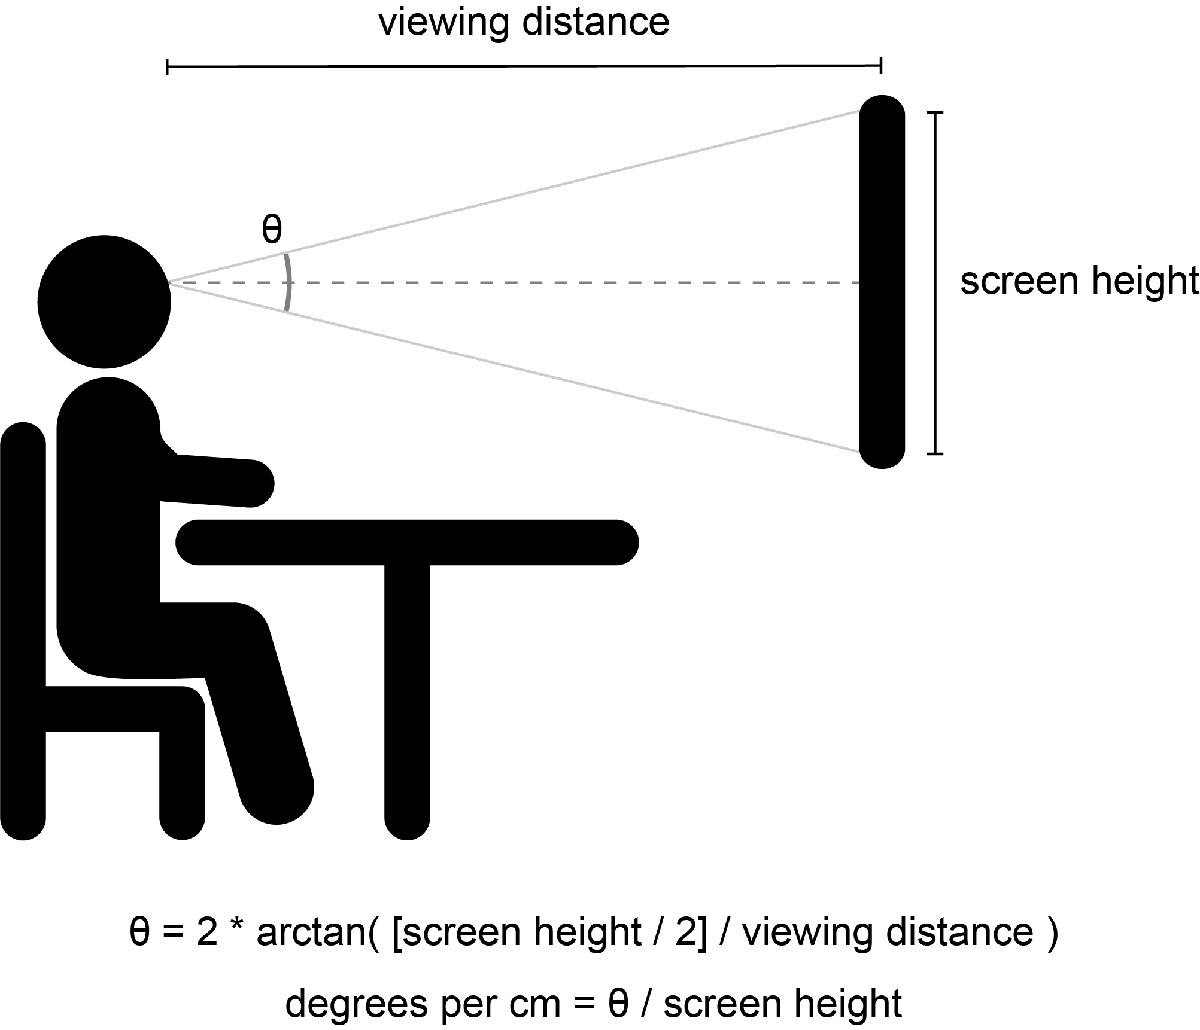

The code below includes rough viewing distance and screen height measurements that should be approximately accurate, but you can replace those numbers with your own if you'd like to be more precise.

% define measurements
% (60 cm distance and 20 cm height should be about right)
viewing_dist_cm = 60;
screen_height_cm = 20;

% calculate cm/deg conversion factor
screen_height_deg = 2 * atan2d(screen_height_cm/2, viewing_dist_cm);
degrees_per_cm = screen_height_deg / screen_height_cm;

% store size parameter used in PsychoPy
% (units = fraction of screen height)
size_fraction = 0.2;  % 20% of screen's pixel height

% convert stimulus size to cm & to degrees
size_cm = size_fraction * screen_height_cm;  % fraction to cm
size_degrees = size_cm * degrees_per_cm;  % cm to deg

% calculate spatial frequency for all stimuli
stim_sf = expt_data.n_cycles ./ size_degrees;

% display spatial frequency levels
disp("spatial frequencies:"); disp(unique(stim_sf).')

spatial frequencies:
    0.2642    0.5284    1.0568    2.1136    4.2273



*Keep in mind:* For these number to be "exact", your head would need to be in a stable position at a fixed viewing distance for the entirety of the experiment (e.g., via a chin rest and forehead bar). Since that was not the case, these spatial frequency numbers are fairly approximate.

#### Determine whether responses were correct or incorrect

For a responses to be correct, the location of the stimulus and the location that the participant reported must match (i.e., both 'left' or both 'right').

% determine whether responses were correct or incorrect
resp_correct = stim_location == resp_location;

% display overall performance
fprintf('overall percentage correct = %.2f%%\n', mean(resp_correct)*100);

overall percentage correct = 77.79%


Your overall percentage correct is displayed above as a ***rough***** sanity check**.

If you're performing below change (50% for this task), that's a sign something may have gone wrong with the experiment or analysis. (Perhaps your screen wasn't displaying the stimuli as intended, or perhaps a software malfunction caused your responses to be logged incorrectly.)

Performance at or near perfect could also be a sign of a problem, as psychophysical experiments generally aim to test the ***limits*** of perception. We can learn ***much*** more from the **sloped** part of a psychometric curve than from its floor or ceiling, so we don't want participants to do too poorly or too well on a task.

Generally, we want a curve to have at least one condition at its floor and one at its ceiling, so an overall performance level right in between chance and perfect (75% in this case) is a good sign.

#### Determine percentage correct per condition

For each contrast and spatial frequency, how often did you choose the correct side of the screen?

% average across responses per contrast level
analysis_table = table(resp_correct, expt_data.contrast, stim_sf, ...
    'VariableNames',["response", "contrast", "sf"]);
expt_results = grpstats(analysis_table, ["contrast", "sf"]);
expt_results = renamevars(expt_results, ...
    ["GroupCount", "mean_response"], ["n_trials", "prob_correct"]);
expt_results.Properties.RowNames = {};

% stash stimulus levels & counts
contrast_levels = unique(expt_results.contrast);
sf_levels = unique(expt_results.sf);

n_contrast = length(contrast_levels);
n_sf = length(sf_levels);

% group results by sf level
results_per_sf = cell(n_sf,1);
for i_sf = 1:n_sf
    % find and stash rows with this SF
    these_rows = expt_results.sf==sf_levels(i_sf);
    results_per_sf{i_sf} = expt_results(these_rows,:);
end; clear these_rows

% display results
disp(expt_results)

    contrast      sf       n_trials    prob_correct
    ________    _______    ________    ____________

      1e-08     0.26421       72         0.47222   
      1e-08     0.52841       72         0.52778   
      1e-08      1.0568       72             0.5   
      1e-08      2.1136       72         0.48611   
      1e-08      4.2273       72         0.54167   
      1e-06     0.26421       48           0.625   
      1e-06     0.52841       48         0.52083   
      1e-06      1.0568       48         0.64583   
      1e-06      2.1136       48         0.66667   
      1e-06      4.2273       48         0.60417   
     0.0001     0.26421       72            0.75   
     0.0001     0.52841       72         0.77778   
     0.0001      1.0568       72         0.77778   
     0.0001      2.1136       72         0.80556   
     0.0001      4.2273       7

You may notice there are quite a few stimulus conditions in this experiment. To be precise:

fprintf("%i contrasts * %i SFs = %i conditions\n", ...
    n_contrast, n_sf, height(expt_results))

8 contrasts * 5 SFs = 40 conditions


#### Plot percentage correct per stimulus condition

How can we start to make sense of all this data from all these different conditions? A plot visualizing each individual trial would probably be too crowded to be very useful, so how about instead, we plot performance as a function of contrast with a separate line for each spatial frequency?

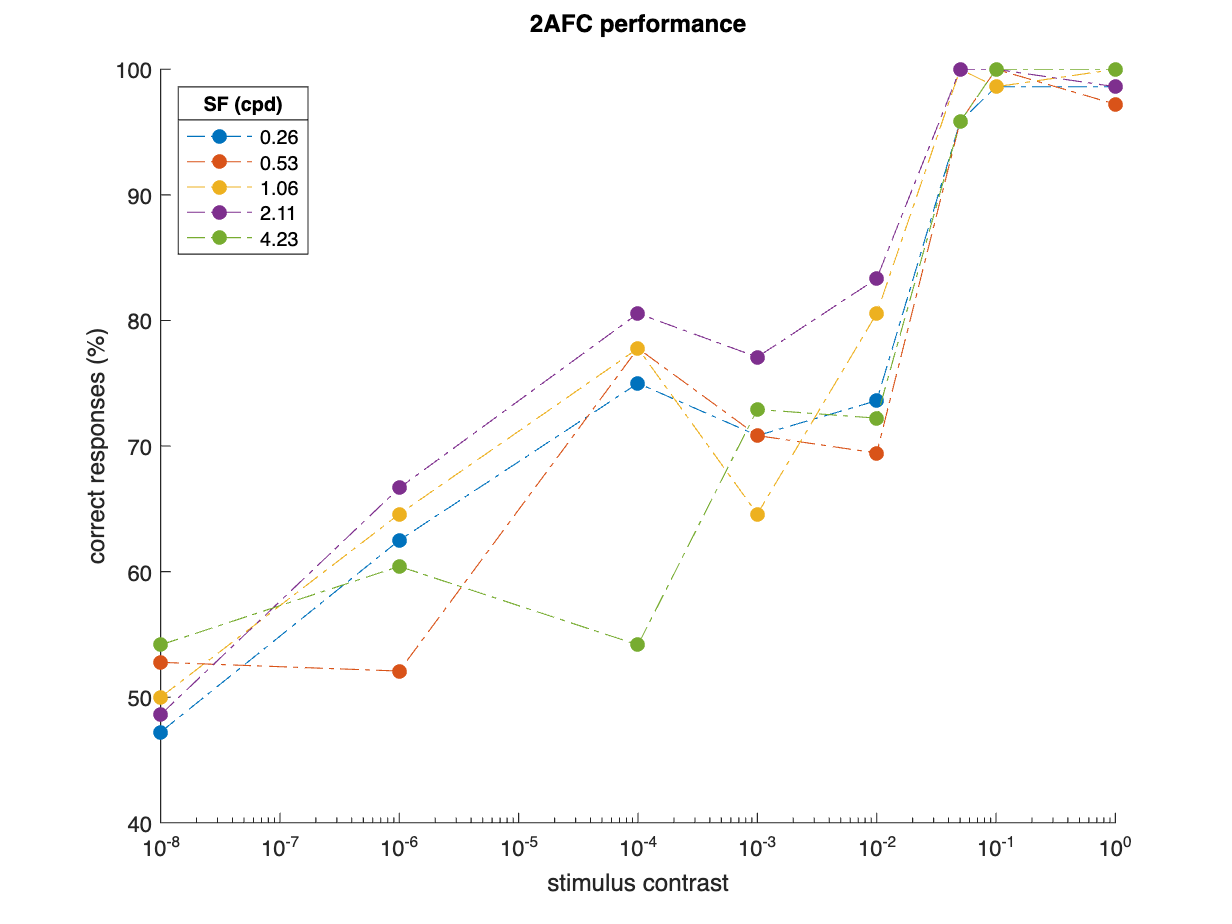

figure; hold on
for i_sf = 1:n_sf
    plot(results_per_sf{i_sf}.contrast, results_per_sf{i_sf}.prob_correct*100, ...
        'LineStyle','-.', 'Marker','.', 'MarkerSize',20);
end
set(gca,'XScale','log')
title(["2AFC performance", ""])
xlabel("stimulus contrast"); ylabel("correct responses (%)")
lgd = legend(num2str(sf_levels,"%.2f"), 'Location','northwest');
title(lgd, "SF (cpd)")

drawnow

**What do you see?** Do you notice anything interesting? How does performance change when spatial frequency increases or decreases?

### Step 4. Fit psychometric curves

By now, you've hopefully gotten a sense of how useful psychometric functions can be, particularly in an experiment with more than one independent variable (i.e., more than one variable that the experimenter manipulates). Since today's experiment has two independent variables, we better fit some curves toot suite!

% define parameter settings
% c(1) = mu
% c(2) = sigma
% c(3) = guess rate
% c(4) = lapse rate
c0 = [0, 1, 0.5, 0];  % starting values
c_lower_b = [-Inf, 0, 0.5, 0];  % lower bounds
c_upper_b = [1, Inf, 0.5, 0];  % upper bounds - force rate values to be 0.5 and 0

% suppress lsqcurvefit auto-printing
opts = optimset('Display','off');

% loop over spatial frequency levels
n_params = length(c0);
psyfit_params = nan(n_sf, n_params);
psyfit_resnorm = nan(n_sf, 1);
for i_sf = 1:n_sf
    % fit function to data
    [this_fit, this_resnorm] = lsqcurvefit(psyfxn, c0, ...
        log10(results_per_sf{i_sf}.contrast), ...  % x values of psychometric curve
        results_per_sf{i_sf}.prob_correct, ...  % y values of psychometric curve
        c_lower_b, c_upper_b, opts);
    psyfit_params(i_sf,:) = this_fit;
    psyfit_resnorm(i_sf,1) = this_resnorm;
end
psyfit_results = array2table([sf_levels, psyfit_params, psyfit_resnorm], ...
    'VariableNames',["sf","mu","sigma","guess_rate","lapse_rate","resnorm"]);

% display results
disp(psyfit_results)

      sf         mu       sigma     guess_rate    lapse_rate    resnorm 
    _______    _______    ______    __________    __________    ________

    0.26421    -3.3663    2.4928       0.5            0          0.03578
    0.52841    -3.1366    2.2498       0.5            0         0.049195
     1.0568    -3.6012    2.4918       0.5            0          0.04787
     2.1136    -4.2363    2.5475       0.5            0         0.022681
     4.2273    -2.5089    1.2304       0.5            0         0.032172



**The more parameters you have, the "noisier" your fits will be.** We're trying to get away with including as few trials as possible in this experiment, which can mean our data will be more noisy (i.e., less reliable). Thus, we've prevented the two rates from varying to try to minimize the noisiness (i.e., increase the reliability) of our fits.

#### Create curves to plot

Let's plot your fitted curves on top of your data to visualize their goodness-of-fit (i.e., how well they represent your measured data). As usual, you'll first need a series of x-values, and you'll then need to evaluate each fitted psychometric function at those x-values to get your y-values.

% pick x values (evenly spaced along log axis)
log_c_levels = log10(contrast_levels);
psy_x = logspace(log_c_levels(1), log_c_levels(end), 300).';

% use psychometric curve function to calculate y values
psy_y = nan(length(psy_x), n_sf);
for i_sf = 1:n_sf
    psy_y(:,i_sf) = psyfxn(psyfit_params(i_sf,:), log10(psy_x));
end

#### Plot fitted psychometric curves

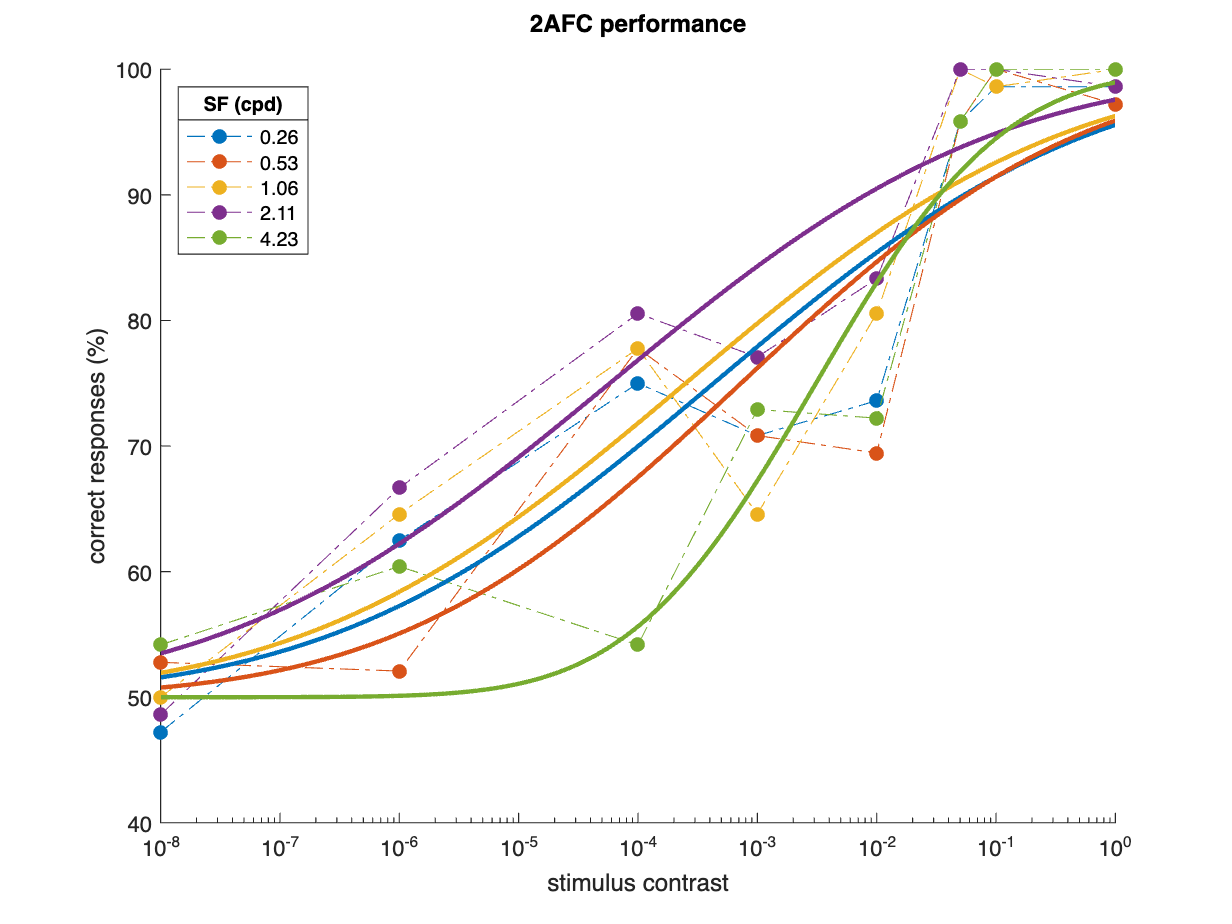

% plot data per spatial frequency
figure; hold on
for i_sf = 1:n_sf
    plot(results_per_sf{i_sf}.contrast, results_per_sf{i_sf}.prob_correct*100, ...
        'Color',rgb_matlab(i_sf,:), 'LineStyle','-.', 'Marker','.', 'MarkerSize',20);
end
set(gca,'XScale','log')
title(["2AFC performance", ""])
xlabel("stimulus contrast"); ylabel("correct responses (%)")

% plot fitted curve per spatial frequency
for i_sf = 1:n_sf
    plot(psy_x, psy_y(:,i_sf)*100, '-', 'Color',rgb_matlab(i_sf,:), 'LineWidth',2)
end
lgd = legend(num2str(sf_levels,"%.2f"), 'Location','northwest');
title(lgd, "SF (cpd)")

drawnow

**What do you think?** Did the optimization procedure do a good job fitting your data? Are some adjustments needed? What do you notice about how the curves change with spatial frequency?

### Step 5. Compare performance across spatial frequencies

Earlier, we covered the utility of computing a single number to represent an entire curve. Now that you're looking at multiple psychometric fits, it's hopefully even easier for you to appreciate why psychophysicists would want to extract a single number (even if some arbitrary decision-making is required along the way).

#### **Compute threshold and sensivity from psychometric curves**

We previously computed 75% threshold and sensivity. Let's repeat those calculations here for each the psychometric curves you measured.

% compute the 75% mark for each psychometric curve
thresh_prob = .75;
c_threshold = nan(n_sf,1);
for i_sf = 1:n_sf
    c_threshold(i_sf) = 10.^(ipsyfxn(psyfit_params(i_sf,:), thresh_prob));
end

% compute sensitivity
c_sensitivity = 1 ./ c_threshold;

% display results
c_results = table(sf_levels, log10(c_threshold), c_sensitivity, ...
    'VariableNames',["sf", "log(threshold)", "sensitivity"]);
disp(c_results)

      sf       log(threshold)    sensitivity
    _______    ______________    ___________

    0.26421       -3.3663          2324.4   
    0.52841       -3.1366          1369.5   
     1.0568       -3.6012          3991.8   
     2.1136       -4.2363           17229   
     4.2273       -2.5089          322.79   



**What do you notice?** What range do each of the values have? Can you spot any trends right away? Does anything stand out or surprise you?

#### **Plot threshold and sensivity as a function of spatial frequency**

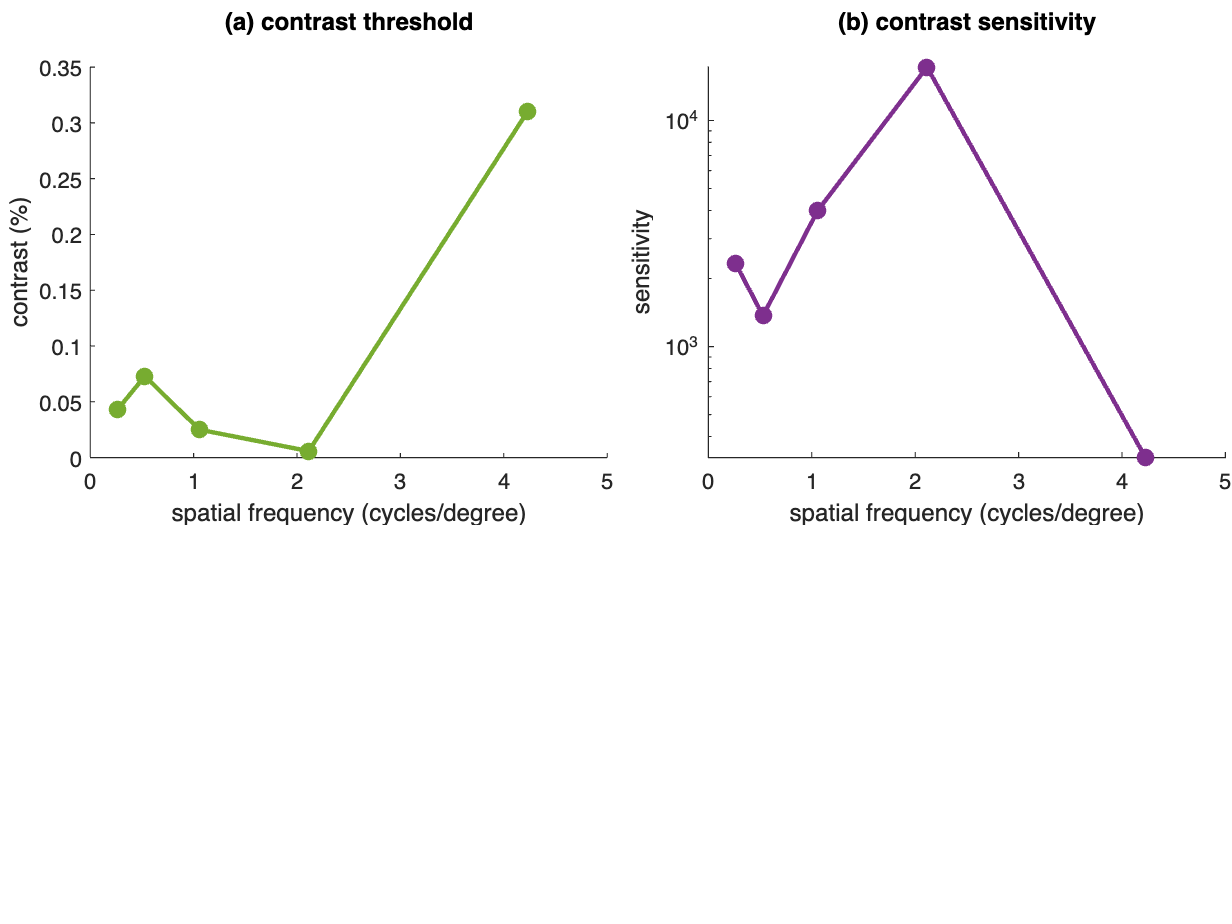

figure; t = tiledlayout(2,2, 'TileSpacing','compact', 'Padding','tight');

% plot threshold values
nexttile
plot(sf_levels, c_threshold*100, '-o', 'LineWidth',2, ...
    'Color',rgb_matlab(5,:), 'MarkerFaceColor',rgb_matlab(5,:))
title(["(a) contrast threshold",""]); box off
xlabel("spatial frequency (cycles/degree)")
ylabel("contrast (%)")

% plot sensitivity values
nexttile
plot(sf_levels, c_sensitivity, '-o', 'LineWidth',2, ...
    'Color',rgb_matlab(4,:), 'MarkerFaceColor',rgb_matlab(4,:))
set(gca,'YScale','log')
title(["(b) contrast sensitivity",""]); box off
xlabel("spatial frequency (cycles/degree)")
ylabel("sensitivity")

drawnow

**What do you think?** What's similar? What's different? Which do you find easier to interpret?

**What about your contrast sensitivity function? **How does your curve compare to a typical example you might see in a textbook? Is the overall shape the same? What, if anything, is different about it?